# Trouver un signal dans une mesure

Vous recevez des données et vous aimeriez savoir si elles correspondent à un flux plus long que vous avez mesuré. La corrélation croisée vous permet de faire cette détermination, même si les données sont corrompues par le bruit.

Chargez dans l'espace de travail l'enregistrement d'un anneau tournant sur une table. 

Découpez un fragment d'une seconde et écoutez-le.

load('Ring.mat')

Time = 0:1/Fs:(length(y)-1)/Fs; 



Full_sig = double(y);

timeA = 7;
timeB = 8;
snip = timeA*Fs:timeB*Fs;

Fragment = Full_sig(snip);

soundsc(Fragment,Fs)


Tracez le signal et le fragment. Mettez en évidence les points d'extrémité du fragment pour référence.

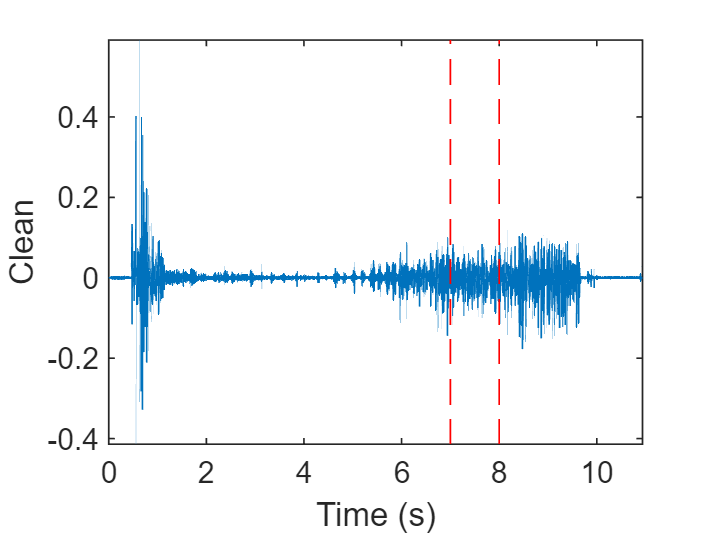

m = min(y);
M = max(y);
plot(Time,Full_sig,[timeA timeB;timeA timeB],[m m;M M],'r--')
xlabel('Time (s)')
ylabel('Clean')
axis tight

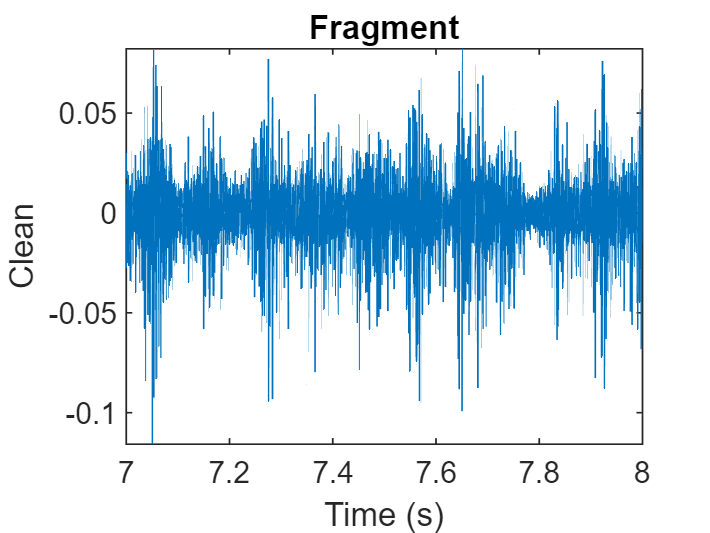


plot(snip/Fs,Fragment)
xlabel('Time (s)')
ylabel('Clean')
title('Fragment')
axis tight

Calculez et tracez la*** corrélation croisée*** du signal complet et du fragment.

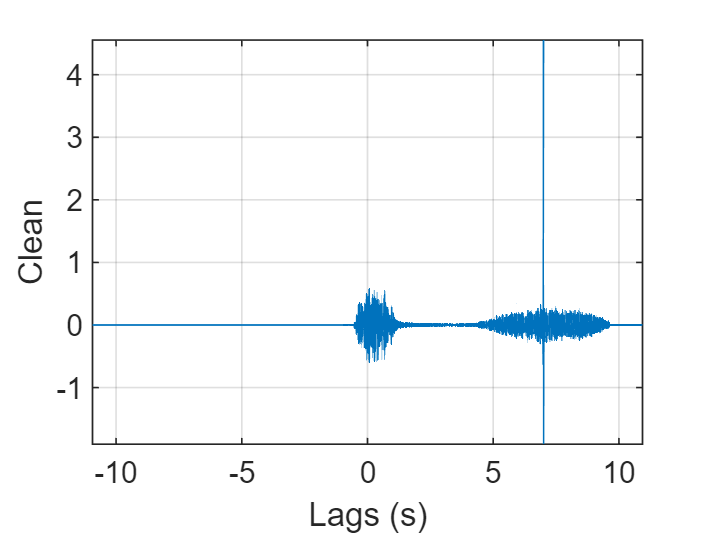

[xCorr,lags] = xcorr(Full_sig,Fragment);

plot(lags/Fs,xCorr)
grid
xlabel('Lags (s)')
ylabel('Clean')
axis tight

Le décalage auquel la corrélation croisée est la plus grande est le délai entre les points de départ des signaux. Replacer le signal et superposer le fragment.

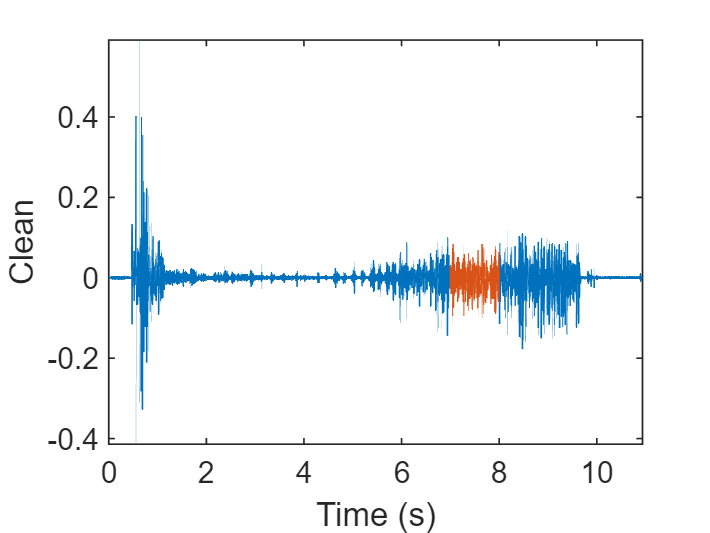

[~,I] = max(abs(xCorr));
maxt = lags(I);

Trial = NaN(size(Full_sig));
Trial(maxt+1:maxt+length(Fragment)) = Fragment;

plot(Time,Full_sig,Time,Trial)
xlabel('Time (s)')
ylabel('Clean')
axis tight

Répétez la procédure, mais ajoutez le bruit séparément du signal et du fragment. Le son ne peut pas être distingué du bruit.

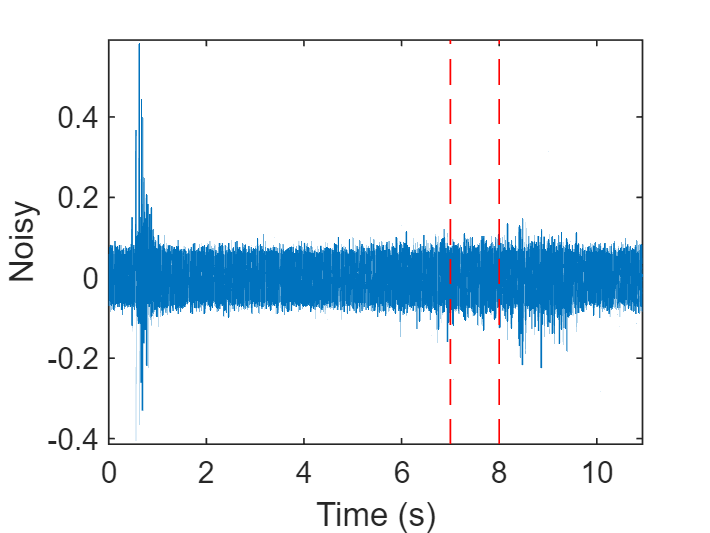

NoiseAmp = 0.2*max(abs(Fragment));

Fragment = Fragment+NoiseAmp*randn(size(Fragment));

Full_sig = Full_sig+NoiseAmp*randn(size(Full_sig));



plot(Time,Full_sig,[timeA timeB;timeA timeB],[m m;M M],'r--')
xlabel('Time (s)')
ylabel('Noisy')
axis tight

soundsc(Fragment,Fs)

La procédure permet de retrouver le fragment manquant malgré le niveau de bruit élevé.

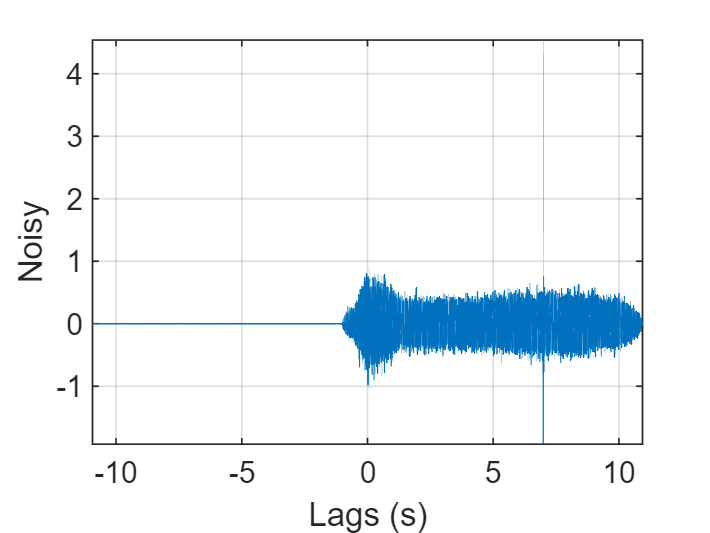

[xCorr,lags] = xcorr(Full_sig,Fragment);

plot(lags/Fs,xCorr)
grid
xlabel('Lags (s)')
ylabel('Noisy')
axis tight

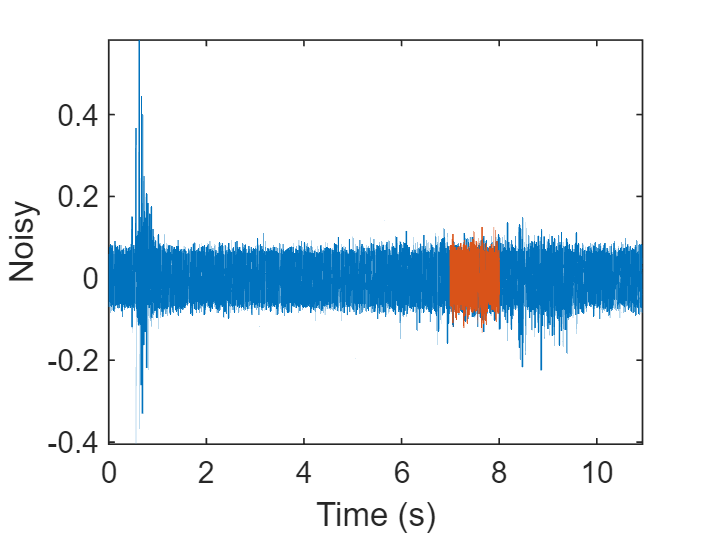


[~,I] = max(abs(xCorr));
maxt = lags(I);

Trial = NaN(size(Full_sig));
Trial(maxt+1:maxt+length(Fragment)) = Fragment;

figure
plot(Time,Full_sig,Time,Trial)
xlabel('Time (s)')
ylabel('Noisy')
axis tight